%I = imread('..\datasets\segmentation-evaluation-database\1obj\100_0109\src_color\100_0109.png');
%I = imread('..\datasets\segmentation-evaluation-database\1obj\100_0497\src_color\100_0497.png');
I = imread('..\datasets\segmentation-evaluation-database\1obj\0677845-r1-067-32_a\src_color\0677845-r1-067-32_a.png');

I = imresize(I, [50 NaN]);
[rows, cols, ~] = size(I);

X = image_transform(I);

[hs, Ks] = search_h(X, 1, 10, 0.9);

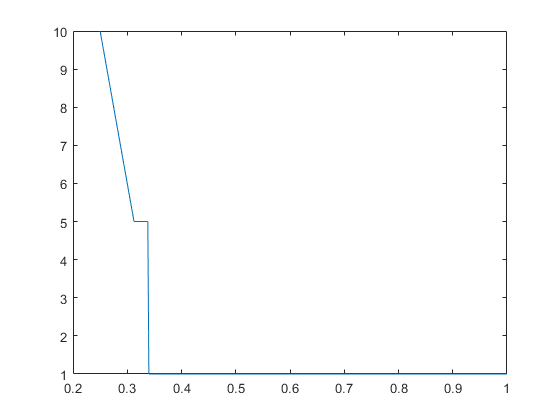

figure
plot(hs, Ks);

h = hs(find(Ks < 2, 1) - 1);

[A, C, T] = mean_shift3(X, h, 0.1);
max(A)

ans = 36

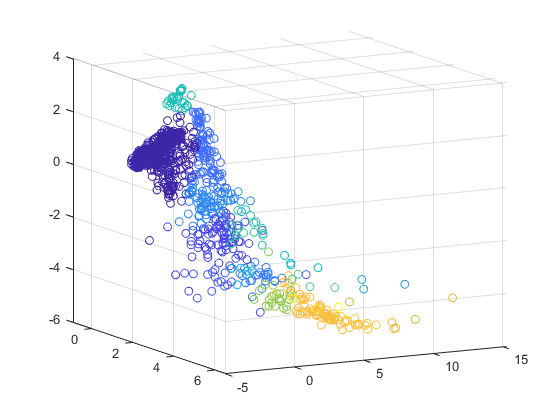

scatter3(X(1,:),X(2,:),X(3,:), [], A);

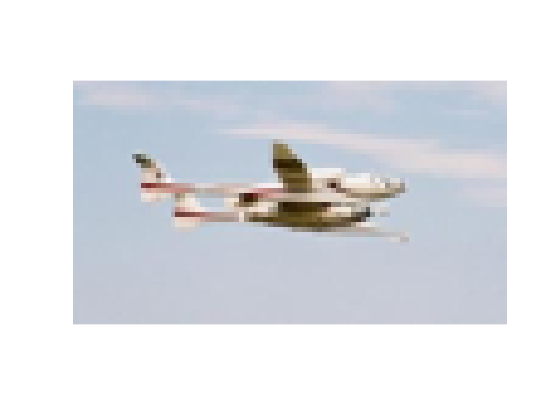

figure
imshow(I, [], 'InitialMagnification', 'fit');

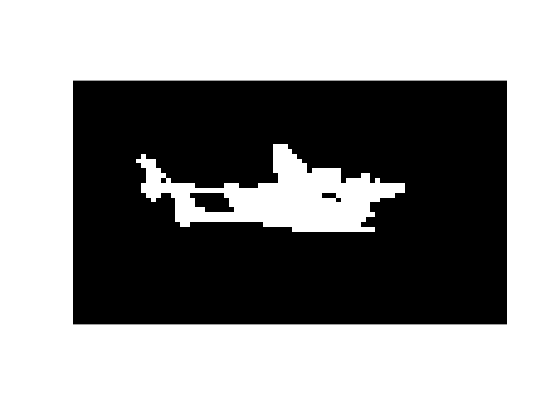

figure
imshow(reshape(A > 0.1 * max(A), rows, cols), [], 'InitialMagnification', 'fit');

function [hs, Ks] = search_h(X, h_start, max_depth, K_threshold)
    [~, n] = size(X);
    hs = [];
    Ks = [];
    h_low = 0;
    h_high = 2 * h_start;
    for i = 1:max_depth
        h = (h_low + h_high) / 2;
        [A, ~, ~] = mean_shift3(X, h, 0.1);
        % effective K: number of biggest clusters needed to amount to
        % K_threshold of the data points
        K = find(cumsum(sort(hist(A, 1:max(A)), 1, 'descend') / n) > K_threshold, 1);
        
        hs = [hs h];
        Ks = [Ks K];
        
        if K == 1
           h_high = h;
        elseif K > 2
           h_low = h;
        else
            break;
        end
    end
    
    [hs, index] = sort(hs);
    Ks = Ks(index);
end